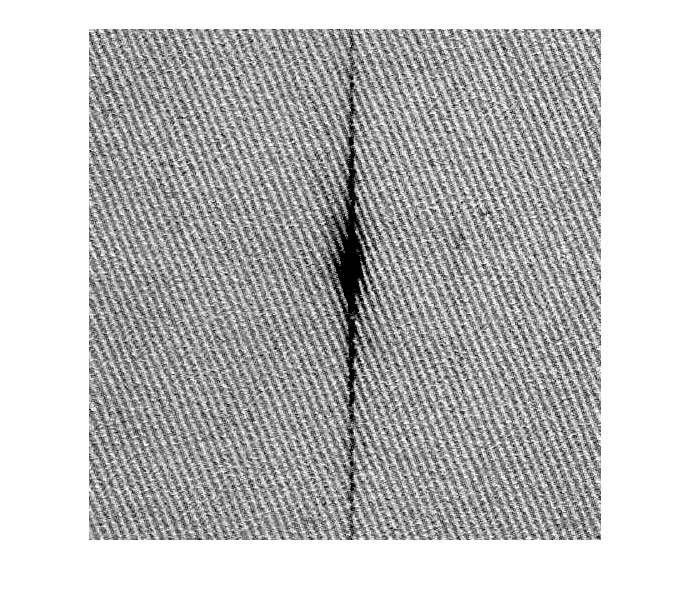

% Martedi 03 Novembre 2020 - Mercoledi 04 Novembre 2020
% Corso di Elaborazione dei Segnali e Immagini
% Docente: Ilaria Boscolo Galazzo 
% Docente Coordinatore: Marco Cristani
% Tutor lab: Christian Joppi 
% LAB2 - parte 2

clear all
close all
clc

%Esercizio 1 - Cross-correlazione 2D normalizzata per trovare difetti su tessuti
B= rgb2gray(imread('i19.jpg'));
[R,C]=size(B);

%Aumento contrasto con imadjust con stretchlim che imposta automaticamente
%la soglia minima del contrasto
A = imadjust(B,stretchlim(B),[]);
figure;
imshow(A);

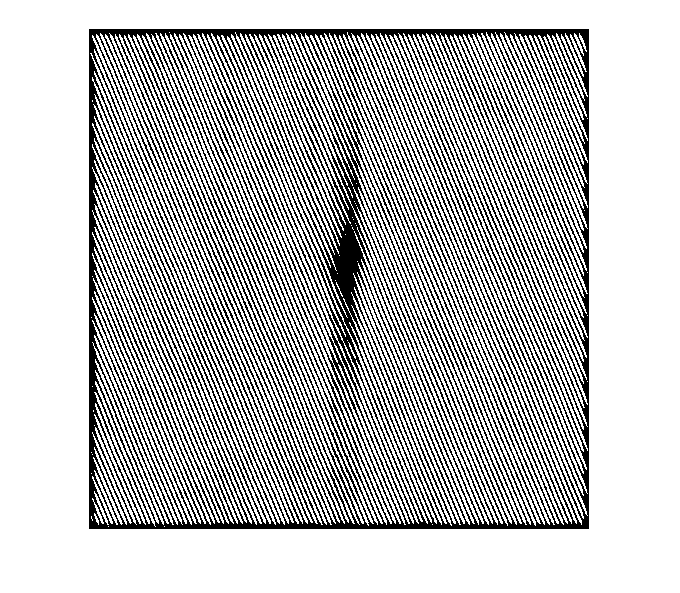


%Ricerca dimensione pattern ideale
i = 0;
j = 1;
inizio = 1;
fine = 8;
times =  linspace(inizio,fine,8); 

%{
%Ricerca massimi senza funzione graycoprops
for i = 0:8
   
        glcm = graycomatrix(A, 'offset', [i 1]);
        plot(times,glcm);
        %times = times-8;
        hold on;            
        inizio = inizio + 8;        
        fine = fine + 8;
        times = linspace(inizio,fine,8);
        
end
%}



%Ricerca dei massimi  di correlazione con funzione graycoprops
offsets0 = [zeros(40,1) (1:40)'];
glcm = graycomatrix(A, 'offset', offsets0);
stats = graycoprops(glcm,'Contrast Correlation');
figure, plot([stats.Correlation]);
title('Texture Correlation as a function of offset');
xlabel('Horizontal Offset')
ylabel('Correlation')    




%Ricerca dei massimi
Massimi = findpeaks(stats.Correlation);
%Pulizia dei massimi non rilevanti
Massimi = Massimi(3:length(Massimi));


%Massimi rilevanti ordinati in ordine decrescente
Massimi = sort(Massimi, 'descend');

%Prendo dal primo posto dell'array il valore corrispondente alla dimensione
%ottimale da utilizzare come pattern
maxValue = Massimi(1);

%Prendo la dimensione ottimale del pattern
patternDimension = find(stats.Correlation == maxValue);

% Definisco i pattern con la dim ottimale ricavata sopra
%Facciamo 4 pattern , 1 per ogni angolo ( sarebbero 8 )
pattern1 = A(1:patternDimension,1:patternDimension); 
pattern2 = A(R-patternDimension:R-1,C-patternDimension:C-1);
pattern3 = A(R-patternDimension:R-1,1:patternDimension);
pattern4 = A(1:patternDimension,C-patternDimension:C-1);



%{
% Definisco una serie di pattern, tutti quadrati 14x14
pattern1 = A(1:28,1:28); 
pattern2 = A(2:29,2:29);
pattern3 = A(R-28:R-1,C-28:C-1);
pattern4 = A(R-29:R-2,C-29:C-2);
pattern5 = A(R-28:R-1,1:28);
pattern6 = A(R-29:R-2,2:29);
pattern7 = A(1:28,C-28:C-1);
pattern8 = A(2:29,C-29:C-2);
%}

%{
figure;
imagesc(A); axis image; colormap gray; hold on;
rectangle('position',[1,1,14,14],'EdgeColor','r'); % pattern1
rectangle('position',[2,2,14,14],'EdgeColor','g'); % pattern2
rectangle('position',[R-13,C-13,14,14],'EdgeColor','b'); %pattern3
rectangle('position',[R-14,C-14,14,14],'EdgeColor','c'); %pattern4
rectangle('position',[1,C-13,14,14],'EdgeColor','m'); %pattern5
rectangle('position',[2,C-13,14,14],'EdgeColor','k'); %pattern6
%}


% Calcolo la xcorr-2D (normalizzata). Size = N+M-1
c1 = normxcorr2(pattern1,A); 
c2 = normxcorr2(pattern2,A);
c3 = normxcorr2(pattern3,A);
c4 = normxcorr2(pattern4,A);

%{
c5 = normxcorr2(pattern5,A);
c6 = normxcorr2(pattern6,A);
c7 = normxcorr2(pattern7,A);
c8 = normxcorr2(pattern8,A);
%}

% From MATLAB Help:
% C = normxcorr2(TEMPLATE,A) computes the normalized cross-correlation of
%     matrices TEMPLATE and A. The matrix A must be larger than the matrix
%     TEMPLATE for the normalization to be meaningful. The values of TEMPLATE
%     cannot all be the same. The resulting matrix C contains correlation
%     coefficients and its values may range from -1.0 to 1.0.

c = (c1+c2+c3+c4)/4; % calcolo media (537x537)
[altezza, larghezza]=size(c);
scarto = (altezza-500)/2;
scarto = cast(scarto,'int32');
c = c(scarto:(end-scarto),scarto:(end-scarto));
figure, surf(abs(c)), shading flat
figure, imagesc(abs(c)), colorbar
c = abs(c);

% Graythreshold
lv = graythresh(c);
maskt = c > (lv);
%maskt = imbinarize(c,lv)
figure; 
imshow(maskt);

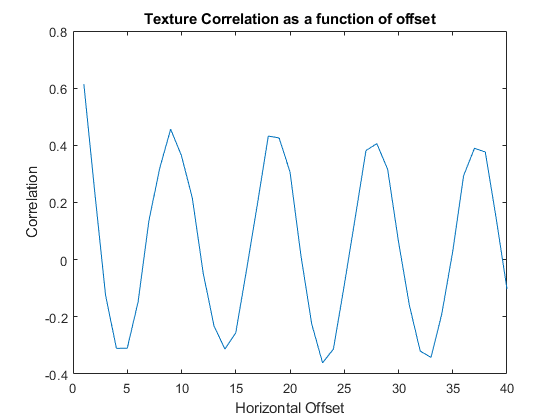

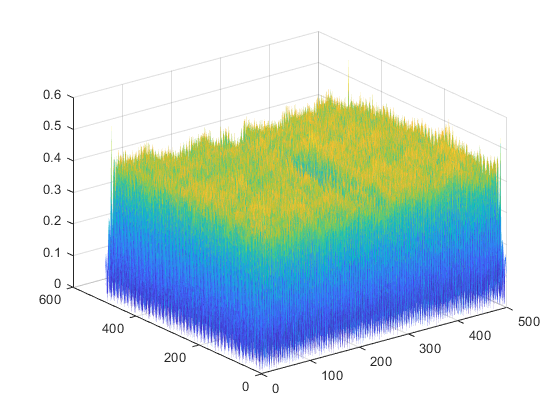

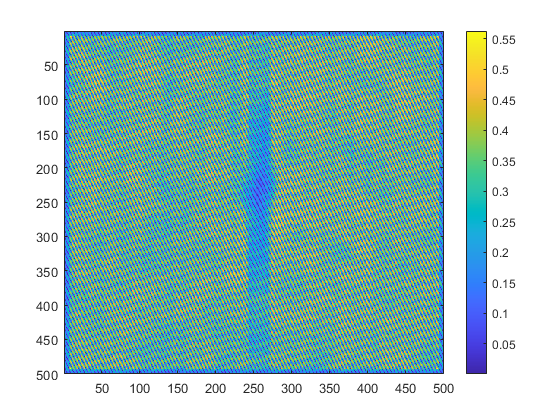

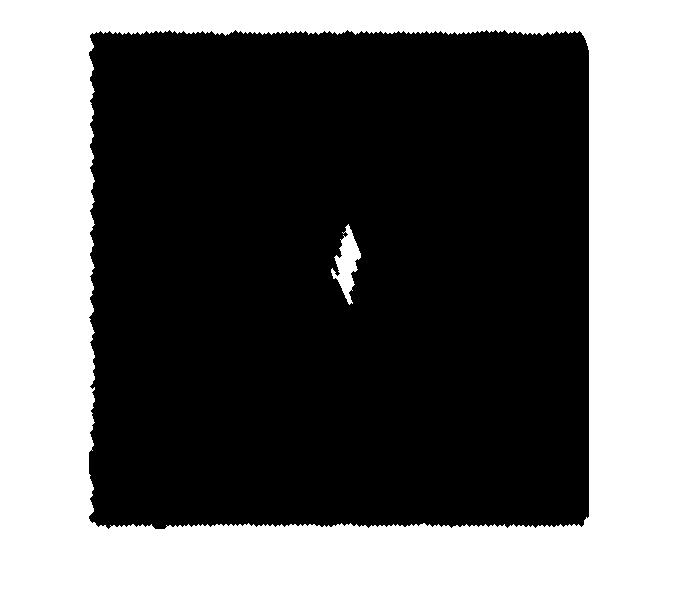


% DANGER ZONE

se3 = strel("disk",2);
maskt = imdilate(maskt , se3);
maskt = imcomplement(maskt);

CC = bwconncomp(maskt);

maskt = bwareafilt(maskt,CC.Connectivity,'largest');

imshow(maskt);

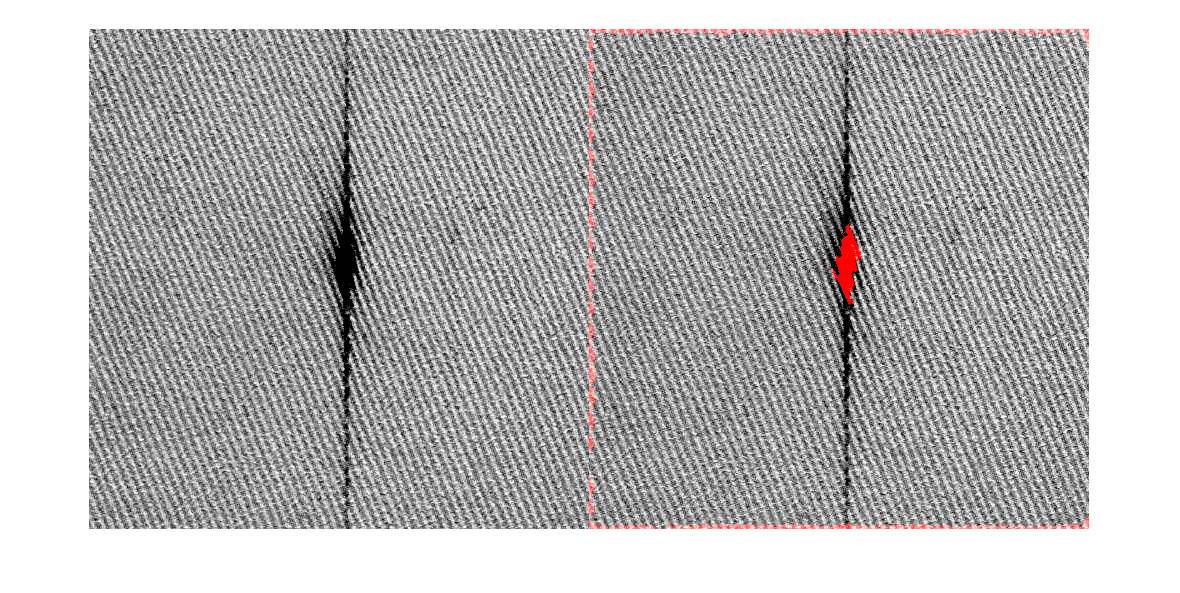

A=A(6:end-7,6:end-7); % Passo da 512x512 a 500x500
A1 = A;
A1(maskt)=255;
Af=cat(3,A1,A,A);
figure;
imshowpair(A,Af,'montage')

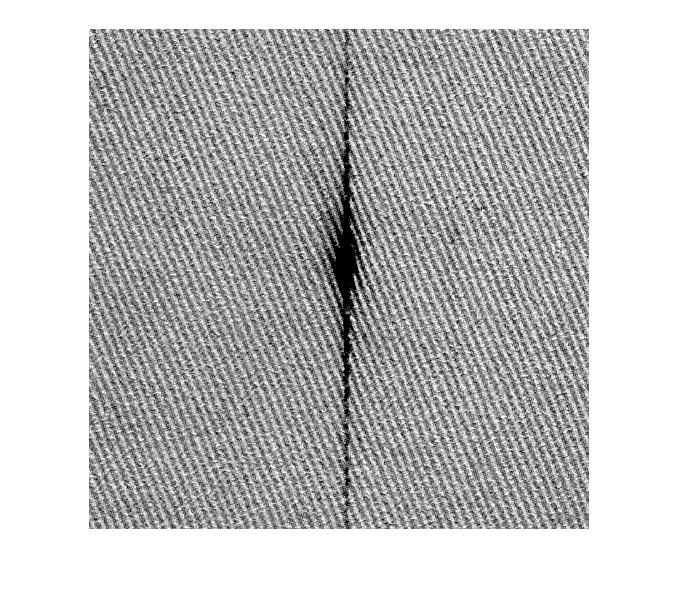


imshow(A);

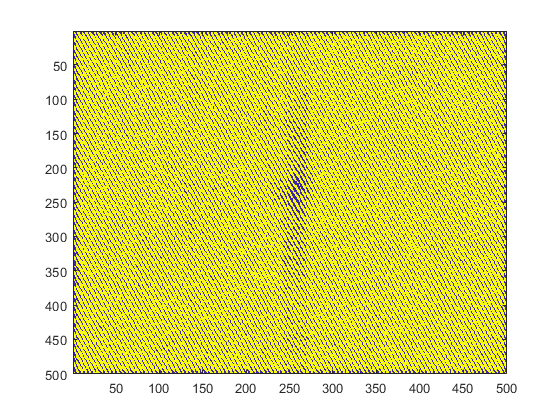

% FINE DANGER ZONE


%Filtro deviazione standard
%sf = stdfilt(c ,ones(3));
%figure;
%imshow(sf);
%mask = sf > (lv);
giallo = mean(c,'all');


mask = c > giallo / 2;
%mask = c > std(maskt,1,'all');
figure, imagesc(mask);

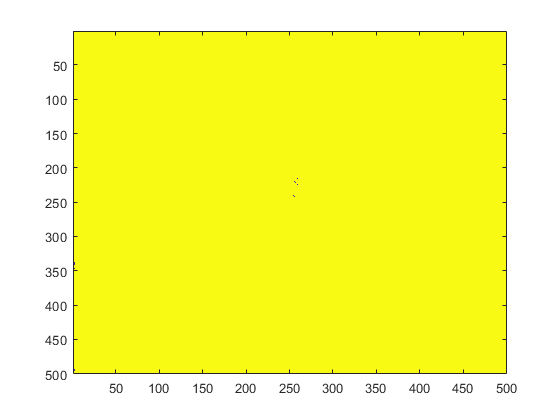

se = strel('square',3); % crea un disco con R = 3%
mask2 = imdilate(mask,se); %Questo è meglio per ora
%mask2 = imopen(mask,se);
figure, imagesc(mask2);

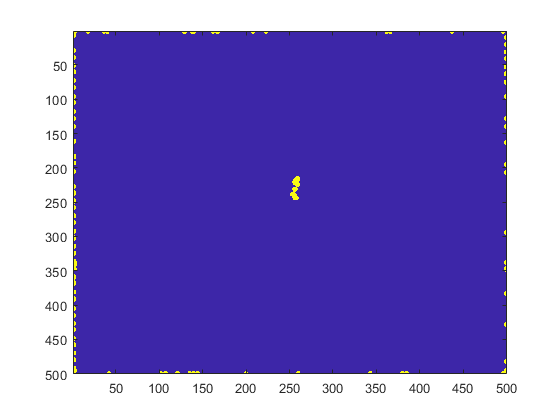



%mask2 = imsubtract(imadd(mask2,imtophat(mask2,se)),imbothat(mask2,se));

mask2 = bwareafilt(mask2,2,'largest');

mask2 = imcomplement(mask2);
se2 = strel('disk',4);
mask3 = imdilate(mask2,se2);
mask3 = bwareafilt(mask3,230,'largest');
figure, imagesc(mask3);


% Nota per IMOPEN = Perform morphological opening.
% The opening operation erodes an image and then dilates the eroded image,
% using the same structuring element for both operations.
% Morphological opening is useful for removing small objects from an image
% while preserving the shape and size of larger objects in the image.
%{
A=A(6:end-7,6:end-7); % Passo da 512x512 a 500x500
A1 = A;
A1(mask2)=255;
Af=cat(3,A1,A,A);
figure;
imshowpair(A,Af,'montage')
%}